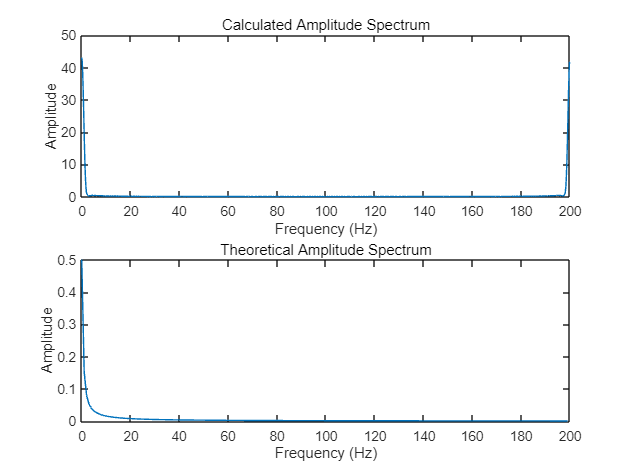

fs = 200; 
T = 1/fs; 
t = 0:T:1-T; 
N = length(t); 
f = (0:N-1)*(fs/N); 


x_t = exp(-2*t); 

X_f_theoretical = 1./(2+1i*2*pi*f); 


window = hamming(N)';


x_t_windowed = x_t .* window; 
N_padded = 1024; 
x_t_padded = [x_t_windowed zeros(1, N_padded - N)]; 


X_f_calculated = fft(x_t_padded, N_padded);
f_padded = (0:N_padded-1)*(fs/N_padded); 


subplot(2,1,1);
plot(f_padded, abs(X_f_calculated));
title('Calculated Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');


subplot(2,1,2);
plot(f, abs(X_f_theoretical));
title('Theoretical Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');



error = abs(X_f_theoretical(1:N) - X_f_calculated(1:N));

error_amplitude = abs(abs(X_f_calculated(1:N)) - abs(X_f_theoretical(1:N)));


mse = mean(error_amplitude.^2);

disp(['Mean Squared Error: ', num2str(mse)]);

Mean Squared Error: 37.5458


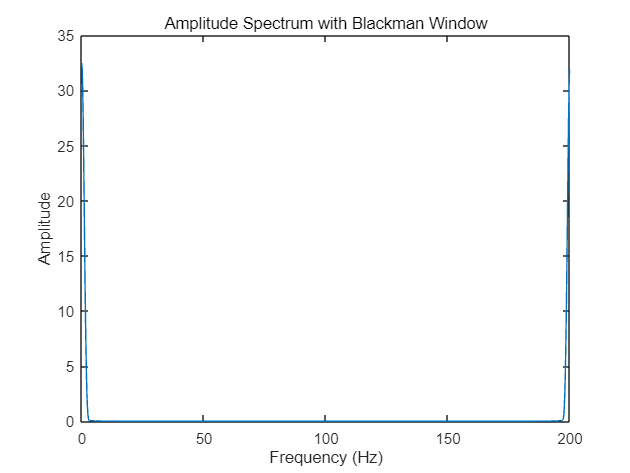


% Improving errors
% Suggestions to improve the error are as follows:
% - Increase the sampling frequency to capture more details of the signal.
% - Use a longer time window to include more periods of the signal, improving the DFT resolution.
% - Apply a better window function to reduce spectral leakage, like a Blackman window.
% - If the signal is long enough, consider segmenting the signal and using the FFT on each segment (Welch's method).

blackman_window = blackman(N)';
x_t_blackman_windowed = x_t .* blackman_window;
X_f_blackman_windowed = fft(x_t_blackman_windowed, N_padded);

figure;
plot(f_padded, abs(X_f_blackman_windowed));
title('Amplitude Spectrum with Blackman Window');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

error_amplitude_blackman = abs(abs(X_f_blackman_windowed(1:N)) - abs(X_f_theoretical(1:N)));
mse_blackman = mean(error_amplitude_blackman.^2);

disp(['Mean Squared Error with Blackman Window: ', num2str(mse_blackman)]);

Mean Squared Error with Blackman Window: 26.0762



f_positive = linspace(0, fs/2, N_padded/2+1); 
X_f_theoretical_values = 1./(2 + 1i*2*pi*f_positive); 

X_f_calculated_positive = X_f_calculated(1:N_padded/2+1);

% Error analysis
errors = abs(X_f_calculated_positive - X_f_theoretical_values);
mean_squared_error = mean(errors.^2);

% Display the error
fprintf('Mean Squared Error: %f\n', mean_squared_error);

Mean Squared Error: 14.535288


fprintf('To improve the error, consider increasing the sampling frequency,\n');

To improve the error, consider increasing the sampling frequency,


fprintf('using a longer data record, employing a different window function,\n');

using a longer data record, employing a different window function,


fprintf('or increasing the zero-padding in the FFT calculation.\n');

or increasing the zero-padding in the FFT calculation.
